
clear all;
close all;

maindir='\\Artemis-pc\e\Data\2024-08-16\';



% x = [7.225 6.280 5.060 3.696 2.260]./7.225;  % mW
% y1 = [0.726078 0.726072 0.726075 0.726102 0.726044];  % +20mA
% err1 = [4 4 4 4 2]*1e-6;
% y2 = [0.726070 0.726073 0.726079 0.726079 0.726096];  % -20mA
% err2 = [4 5 4 4 3]*1e-6;
% 
% 
% y = (y1+y2)./2;
% err = (err1.^2+err2.^2).^0.5/2;
% w = 1./err.^2;
% y_mean = mean(y);
% err_mean = std(y,w)/sqrt(5-1);
% 
% w = 1./err.^2;

x = [1 0.82 0.55 0.32 0.15];
y1 = [0.726078 0.726082 0.726074 0.726073 0.726064];   % Global Fit
err1 = [6 6 5 5 4].*1e-6;
w1 = 1./err1.^2;
y_mean1 = sum(y1.*w1)/sum(w1);
err_mean1 = std(y1,w1);
err_mean1 = sqrt(sum(w1.*((y1-y_mean1).^2 + 1./w1)) / sum(w1));

chi1_s = 0;
for k1 = 1:length(x)
    temp1(k1) = (y1(k1)-y_mean1)^2;
    chi1_s = chi1_s + w1(k1)*temp1(k1);
end
chi1_s = chi1_s/(length(x)-1);

if chi1_s > 1
    err_chi1 = err_mean1*sqrt(chi1_s);
elseif chi1_s <= 1
    err_chi1 = err_mean1;
end

y2 = [0.726074 0.726083 0.726075 0.726071 0.726066];   % Linear Fit
err2 = [3 7 7 5 5].*1e-6;
w2 = 1./err2.^2;
y_mean2 = sum(y2.*w2)/sum(w2);
err_mean2 = std(y2,w2);
err_mean1 = sqrt(sum(w2.*((y2-y_mean2).^2 + 1./w2)) / sum(w2));

chi2_s = 0;
for k2 = 1:length(x)
    temp2(k2) = (y2(k2)-y_mean2)^2;
    chi2_s = chi2_s + w2(k2)*temp2(k2);
end
chi2_s = chi2_s/(length(x)-1);

if chi2_s > 1
    err_chi2 = err_mean2*sqrt(chi2_s);
elseif chi2_s <= 1
    err_chi2 = err_mean2;
end



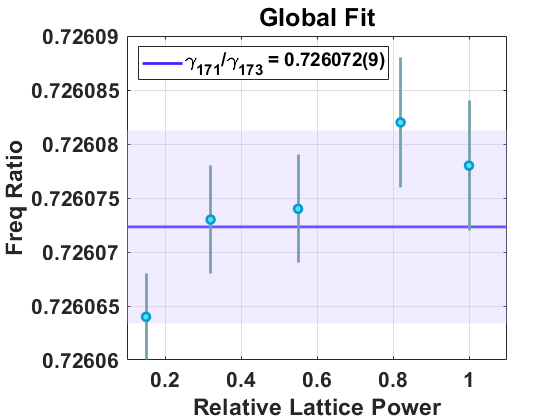


x_low = 0.1;
x_high = 1.1;

f1 = figure; hold on;

plot([x_low x_high],[y_mean1 y_mean1],Color=[0.22 0.14 1],LineWidth=2);
n1 = [1 2 3 4];
patch_list = [x_low y_mean1-err_chi1;x_high y_mean1-err_chi1;x_high y_mean1+err_chi1;x_low y_mean1+err_chi1];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');

E1 = errorbar(x,y1,err1,'o', LineWidth=2, MarkerSize=6);

E1.CapSize = 0;
E1.MarkerEdgeColor = [0.04,0.59,0.83];
E1.MarkerFaceColor = [0.29,0.91,0.91];
E1.Color = [0.45,0.63,0.67];

set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear','Box','on');
%ylim([0.7258 0.7275]);
xlim([x_low x_high]);
grid on;


xlabel('Relative Lattice Power');
ylabel('Freq Ratio');
title('Global Fit','FontSize',19,'FontName','Arial','FontWeight','bold');

legend(['\gamma_{171}/\gamma_{173} = ',num2str(roundn(y_mean1,-6),'%.6f'),'(',num2str(round(err_chi1*1e6)),')'], ...
    'Location','northwest','FontSize',14);

hold off;

set(gcf,'Visible','on');


savefig(f1,[maindir,'Ratio_vs_I_Global.fig']);
saveas(f1,[maindir,'Ratio_vs_I_Global.png']);

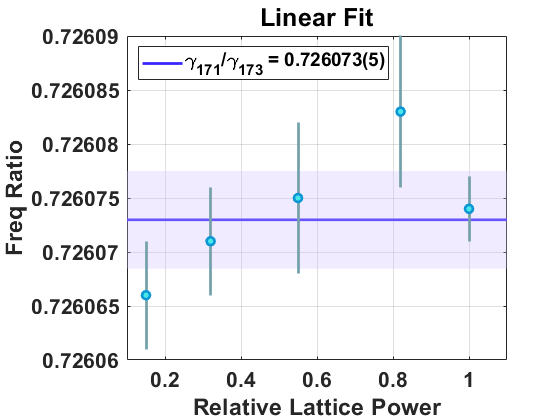


f2 = figure; hold on;

plot([x_low x_high],[y_mean2 y_mean2],Color=[0.22 0.14 1],LineWidth=2);
n2 = [1 2 3 4];
patch_list = [x_low y_mean2-err_chi2;x_high y_mean2-err_chi2;x_high y_mean2+err_chi2;x_low y_mean2+err_chi2];
patch('Faces',n2,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');

E2 = errorbar(x,y2,err2,'o', LineWidth=2, MarkerSize=6);

E2.CapSize = 0;
E2.MarkerEdgeColor = [0.04,0.59,0.83];
E2.MarkerFaceColor = [0.29,0.91,0.91];
E2.Color = [0.45,0.63,0.67];

set(gca,'FontSize',16,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear','Box','on');
%ylim([0.7258 0.7275]);
xlim([x_low x_high]);
grid on;


xlabel('Relative Lattice Power');
ylabel('Freq Ratio');
title('Linear Fit','FontSize',19,'FontName','Arial','FontWeight','bold');
legend(['\gamma_{171}/\gamma_{173} = ',num2str(roundn(y_mean2,-6),'%.6f'),'(',num2str(round(err_chi2*1e6)),')'], ...
    'Location','northwest','FontSize',14);

hold off;

set(gcf,'Visible','on');


savefig(f2,[maindir,'Ratio_vs_I_Linear.fig']);
saveas(f2,[maindir,'Ratio_vs_I_Linear.png']);


% diff = (y1-y2)./2;
% err = (err1.^2+err2.^2).^0.5/2;
% 
% w = 1./err.^2;
% 
% 
% f3 = figure; hold on;
% E3 = errorbar(x,diff,err,'o', LineWidth=2, MarkerSize=6);
% 
% E3.CapSize = 0;
% E3.MarkerEdgeColor = [0.04,0.59,0.83];
% E3.MarkerFaceColor = [0.29,0.91,0.91];
% E3.Color = [0.45,0.63,0.67];
% 
% set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
%     'YScale','linear','XScale','linear');
% %ylim([0.7258 0.7275]);
% xlim([0.2 1.10]);
% grid on;
% 
% 
% xlabel('Lattice Relative Power mW');
% ylabel('Diff Ratio');
% 
% hold off;
% 
% set(gcf,'Visible','on');



save([maindir,'FreqRatio_I.mat']);